# SIR Model Simulation

## Intro

The **SIR Model** has been developed to simulate an epidemic over time. The model consists of a system of 3 differential equations that express the rates of change of 3 variables over time. The 3 variables are:

1. **S** - the susceptibles of getting the infection;

2. **I** - the infected;

3. **R** - the recovered from the infection.

## The Model

Here follow the 3 equations that govern the model dynamics:


$$\begin{array}{l}
\frac{\mathrm{dS}}{\mathrm{dt}}=-\beta \cdot \mathrm{S}\cdot \mathrm{I}+\delta \cdot \mathrm{R}\\
\frac{\mathrm{dI}}{\mathrm{dt}}=\beta \cdot \mathrm{S}\cdot \mathrm{I}-\gamma \cdot \mathrm{I}\\
\frac{\mathrm{dR}}{\mathrm{dt}}=\gamma \cdot \mathrm{I}-\delta \cdot \mathrm{R}
\end{array}$$


## Model simulation

The following is a simulation of the model described above.

% Model parameters
beta = 5*10^-9; % rate of infection
gamma = 0.12; % rate of recovery (try also 0.07)
delta = 0.0; % rate of immunity loss
N = 6*10^7; % Total population N = S + I + R
I0 = 10; % initial number of infected
T = 300; % period of 300 days
dt = 1/4; % time interval of 6 hours (1/4 of a day)
fprintf('Value of parameter R0 is %.2f',N*beta/gamma)

Value of parameter R0 is 2.50

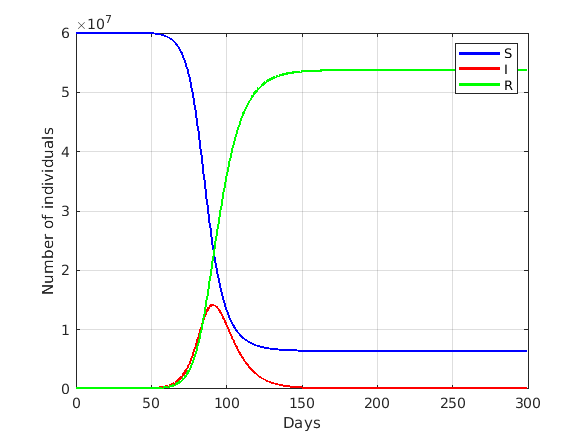

% Calculate the model
[S,I,R] = sir_model(beta,gamma,delta,N,I0,T,dt);
% Plots that display the epidemic outbreak
tt = 0:dt:T-dt;
% Curve
plot(tt,S,'b',tt,I,'r',tt,R,'g','LineWidth',2); grid on;
xlabel('Days'); ylabel('Number of individuals');
legend('S','I','R');

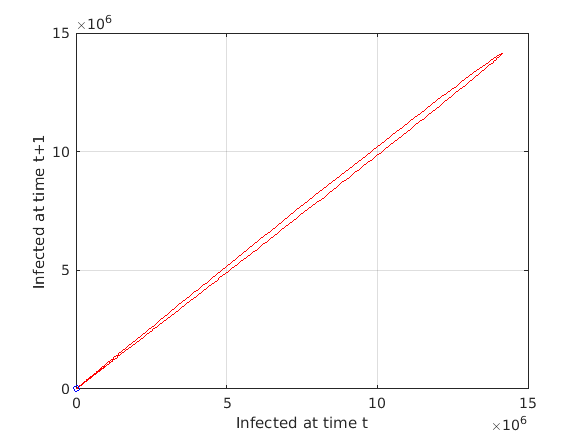

% Map
plot(I(1:(T/dt)-1),I(2:T/dt),"LineWidth",1,"Color",'r');
hold on; grid on;
plot(I(2),I(1),'ob','MarkerSize',4);
xlabel('Infected at time t'); ylabel('Infected at time t+1');
hold off;

## What if we consider immunity loss?

In a more general model, recovered individuals could lose their immunity after some time. Let’s assume that immunity is lost, on average, after 60 days from recovery (delta = 1/60), and display the new simulation.

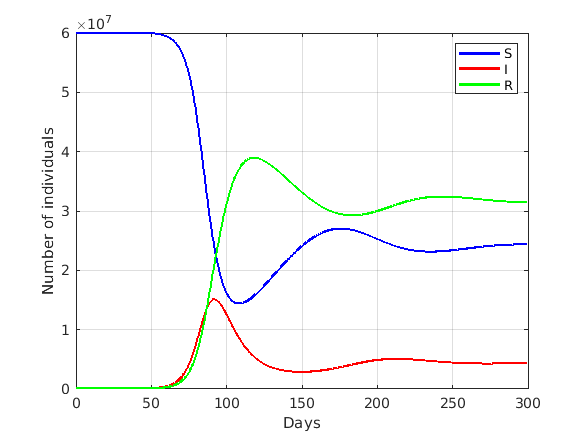

delta = 1/60; % rate of immunity loss
% Calculate the model
[S,I,R] = sir_model(beta,gamma,delta,N,I0,T,dt);
% Curve
plot(tt,S,'b',tt,I,'r',tt,R,'g','LineWidth',2); grid on;
xlabel('Days');ylabel('Number of individuals');
legend('S','I','R');

Function that calculates the model evolution over a time period T.

function [S,I,R] = sir_model(beta,gamma,delta,N,I0,T,dt)
    % if delta = 0 we assume a model without immunity loss
    S = zeros(1,T/dt);
    S(1) = N;
    I = zeros(1,T/dt);
    I(1) = I0;
    R = zeros(1,T/dt);
    for tt = 1:(T/dt)-1
        % Equations of the model
        dS = (-beta*I(tt)*S(tt) + delta*R(tt)) * dt;
        dI = (beta*I(tt)*S(tt) - gamma*I(tt)) * dt;
        dR = (gamma*I(tt) - delta*R(tt)) * dt;
        S(tt+1) = S(tt) + dS;
        I(tt+1) = I(tt) + dI;
        R(tt+1) = R(tt) + dR;
    end
end
